## Session 4

# **Comparing Means**

## **Parametric Statistical Tests**

**Assumptions of Parametric Tests**:

- **Normality**: Data (or residuals) are normally distributed.

- **Homogeneity of Variance**: Variances of the populations from which samples are drawn are equal.

- **Independence**: Observations are independent of each other (unless explicitly designed as paired/repeated measures).

- **Interval/Ratio Data**: Dependent variable is measured on an interval or ratio scale.

**t-tests**:

- **Purpose**: Comparing means of one or two groups.

- **One-Sample t-test**: Compares the mean of a single sample to a known or hypothesized population mean (e.g., "Is the average ERP amplitude significantly different from zero?").

- **Independent Samples t-test**: Compares the means of two *independent* groups (e.g., "Is the ERP amplitude different between patients and controls?").

- **Paired Samples t-test**: Compares the means of two *related* samples (e.g., "Is the ERP amplitude different between Condition A and Condition B in the *same* subjects?").

**ANOVA (Analysis of Variance)**:

- **Purpose**: Comparing means of *three or more* groups or conditions. Extends the t-test.

- **Concept of F-statistic**: Ratio of variance *between* groups to variance *within* groups. A large F-value suggests group means are more different than within-group variability.

- **One-Way ANOVA**: For one categorical independent variable with 3+ levels (e.g., comparing ERP amplitude across three stimulus types).

- **Multi-factor ANOVA (e.g., Two-Way ANOVA)**: For designs with two or more categorical independent variables (e.g., comparing ERP amplitude by stimulus type AND gender).

**Post-hoc Tests**:

- **Why Needed**: A significant ANOVA only tells you that *at least one*  group mean is different, not *which* specific groups differ.

- **Purpose**: Perform pairwise comparisons between group means after a significant ANOVA.

- **Examples**: Tukey's Honestly Significant Difference (HSD), Bonferroni correction (adjusts p-values for multiple comparisons).

**Non-parametric Test**

- **When to Use**:

- When parametric assumptions (especially normality) are severely violated

- When data is ordinal or ranked.

- When sample sizes are very small

**Brief Overview**:

- **Wilcoxon Rank-Sum Test (Mann-Whitney U-test)**: Non-parametric alternative to the independent samples t-test. Compares medians or distributions, not means.

- **Wilcoxon Signed-Rank Test**: Non-parametric alternative to the paired samples t-test. Compares medians of paired differences.

- **Trade-offs**:

- **Advantages**: Fewer assumptions, robust to outliers.

- **Disadvantages**: Generally less statistical power than parametric tests if assumptions are met.

## What Is a Brain–Computer Interface (BCI)?

A **Brain–Computer Interface (BCI)** is a system that **allows direct communication between the brain and an external device**—without using the body's normal pathways (muscles or nerves).

BCIs detect and interpret patterns in brain activity and translate them into actions such as:

- Moving a cursor on a screen

- Controlling a robotic arm

- Selecting letters on a speller

- Operating assistive devices for people with paralysis

**How BCIs Work (Simple Overview)**

A typical BCI system follows these steps:

**        1. Signal Acquisition**

- Electrodes measure brain activity (commonly EEG on the scalp).

**        2. Preprocessing**

- Noise and artifacts (eye blinks, muscle activity) are removed.

- Signals may be filtered (e.g., 8–30 Hz for motor imagery).

**        3. Feature Extraction**

- Extract meaningful information, like changes in rhythmic activity.

**        4. Classification**

- A machine-learning model identifies what the user intends (e.g., imagining left hand vs. right hand).

**        5. Control Output**

- The recognized intention is translated into a command—moving a cursor, selecting an option, etc.

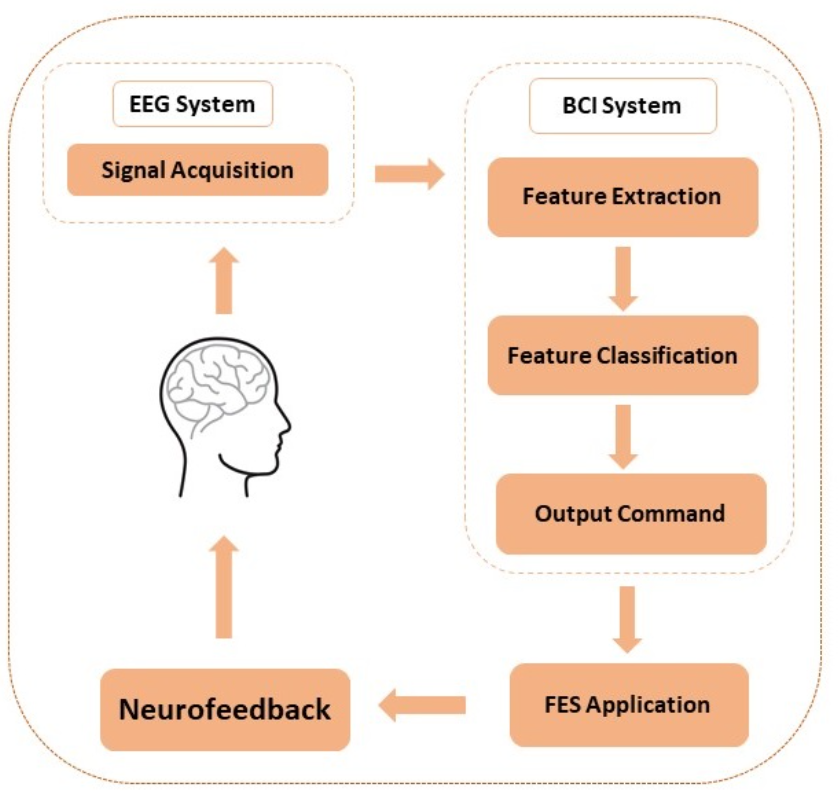

## What Is a Motor Imagery (MI) Task?

Motor Imagery (MI) is the mental simulation of movement **without actually moving**.

For example:

- Imagining moving your **left hand**

- Imagining moving your **right hand**

- Imagining **foot** movement

**Why MI Works for BCIs**

When you imagine a movement, your brain’s motor cortex becomes active **in patterns similar to real movement**.

The key EEG rhythms [involved](https://www.sciencedirect.com/science/article/abs/pii/S1388245708012601):

- **μ-rhythm (8–13 Hz)**

- **β-rhythm (13–30 Hz)**

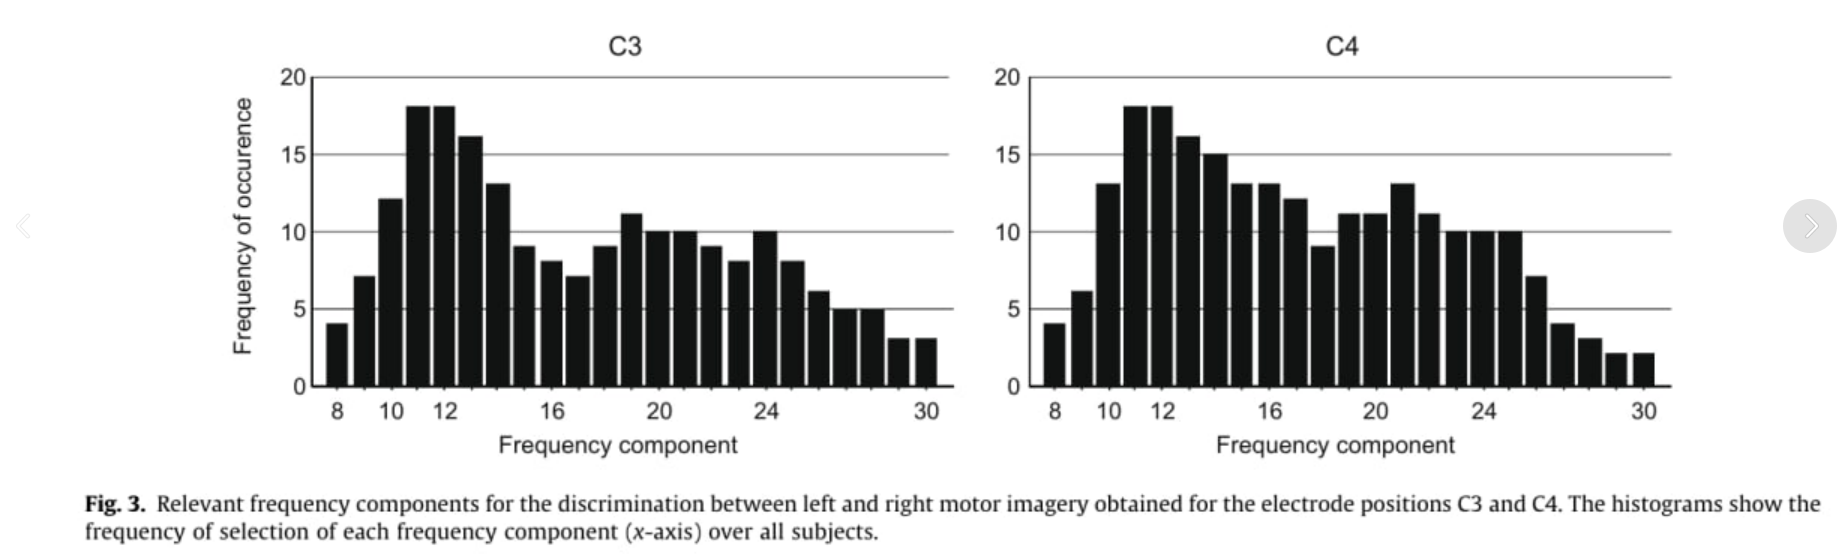

MI causes **event-related desynchronization (ERD)** in the area corresponding to the imagined body part.

Example:

- Imagining right-hand movement → activity decreases over **left motor cortex** (C3 region)

- Imagining left-hand movement → activity decreases over **right motor cortex** (C4 region)

This change can be detected by EEG, allowing the system to determine *which movement you imagined*.

### Motor Imagery Used in BCI Competition IV Dataset I

The dataset you’re working with includes MI tasks:

- **Left hand imagery**

- **Right hand imagery**

- **Foot imagery**

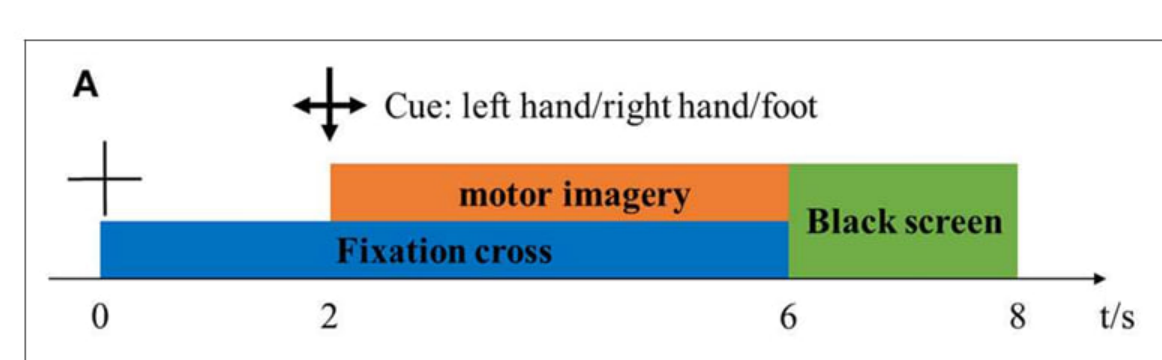

Participants did not move their body—only **imagined** the movements.

The EEG signals during these intervals are what you classify in MI-BCI research.

Here is a schematic illustration:

#### Why MI-BCI Is Important

Motor imagery BCIs are among the most widely studied because:

- They **do not require actual movement**, useful for paralyzed patients.

- Training improves performance (like learning a skill).

- They help in **neurorehabilitation** after stroke.

clear;
clc;
warning('off', 'all');
restoredefaultpath
addpath('C:\matlab_path\eeglab2025.0.0');
eeglab('nogui');

eeglab: options file is C:\Users\abolfazl\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "EEG-BIDS" v? (see >> help eegplugin_eegbids) - new version 10.4 available
EEGLAB: adding "ICLabel" v? (see >> help eegplugin_iclabel) - new version 1.7 available (critical bug fix)
EEGLAB: adding "clean_rawdata" v? (see >> help eegplugin_clean_rawdata) - new version 2.11 available
EEGLAB: adding "dipfit" v? (see >> help eegplugin_dipfit) - new version 5.6 available
EEGLAB: adding "firfilt" v? (see >> help eegplugin_firfilt) - new version 2.8 available


%% Load dataset
load("BCICIV_calib_ds1a.mat");   % loads: cnt, mrk, nfo

%% Convert EEG from int16 → microvolts
cnt = double(cnt) * 0.1;         % 0.1 µV per LSB

%% Create EEGLAB EEG structure
EEG = pop_importdata( ...
    'dataformat','array', ...
    'data',     cnt', ...     % EEGLAB expects channels × samples
    'srate',    nfo.fs, ...
    'subject',  'BCI', ...
    'nbchan',   size(cnt,2), ...
    'chanlocs', [] );

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (190594) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



%% Add channel labels
EEG.chanlocs = struct('labels', nfo.clab);

%% Add events (markers)
nEvents = length(mrk.pos);
EEG.event = [];

for i = 1:nEvents
    EEG.event(i).type  = mrk.y(i);      % class label (-1 or +1)
    EEG.event(i).latency = mrk.pos(i);  % sample index of cue
    EEG.event(i).duration = 0;
end

EEG = eeg_checkset(EEG, 'eventconsistency');

%% ----------- APPLY 8–16 Hz FILTER USING EEGLAB ----------------
filtered_EEG = pop_eegfiltnew(EEG, 'locutoff', 8, 'hicutoff', 16);

pop_eegfiltnew() - performing 167 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1.98795180722892 Hz
pop_eegfiltnew() - passband edge(s): [8 16] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7.00602409638554 16.9939759036145] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00





disp('Filtering complete (8–16 Hz).');

Filtering complete (8–16 Hz).


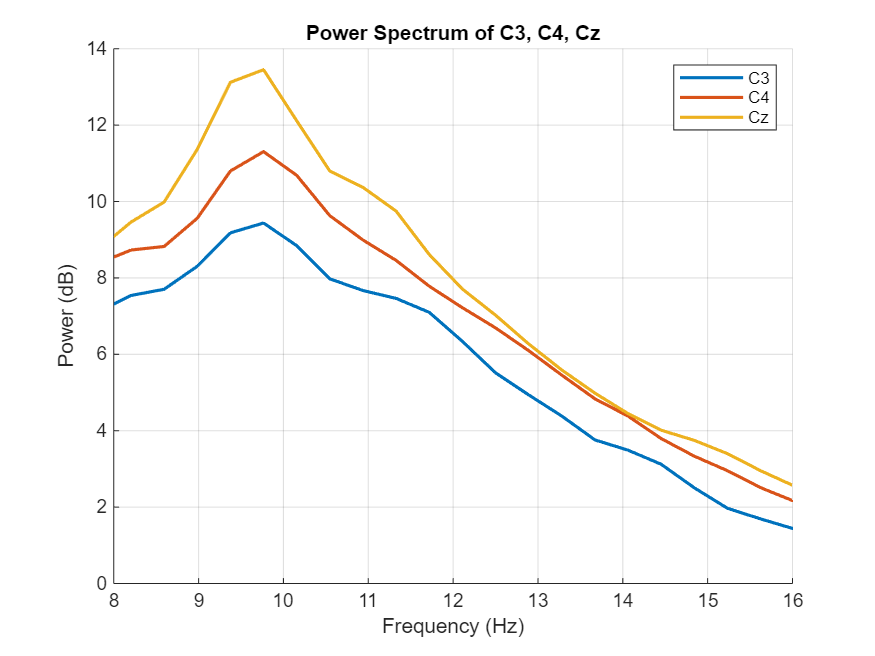

%% Extract channels
channels = {'C3','C4','Cz'};
chanIdx = find(ismember({filtered_EEG.chanlocs.labels}, channels));

% Sampling rate
fs = filtered_EEG.srate;

% Prepare figure
figure; hold on;

for i = 1:length(chanIdx)
    chan = chanIdx(i);

    % Get signal
    x = filtered_EEG.data(chan, :);

    % Compute power spectrum using pwelch
    [pxx, f] = pwelch(x, fs*2, fs, [], fs);

    % Plot
    plot(f,10*log10(pxx), 'LineWidth', 1.5)
end

title("Power Spectrum of C3, C4, Cz");
xlabel("Frequency (Hz)");
ylabel("Power (dB)");
legend(channels);
grid on;
xlim([8 16]);   % focus on motor imagery band

%% =======================
% 1. Epoch per class separately
% =======================
epochWindow = [-1 4];   % seconds relative to cue

EEG_class1 = pop_epoch(filtered_EEG, {'-1'}, epochWindow);   % class -1

pop_epoch():100 epochs selected
Epoching...
pop_epoch():100 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_class2 = pop_epoch(filtered_EEG, {'1'}, epochWindow);    % class +1

pop_epoch():100 epochs selected
Epoching...
pop_epoch():100 epochs generated
pop_epoch(): checking epochs for data discontinuity



% Baseline correction (-100ms to 0ms)
EEG_class1 = pop_rmbase(EEG_class1, [-100 0]);

pop_rmbase(): Removing baseline...


EEG_class2 = pop_rmbase(EEG_class2, [-100 0]);

pop_rmbase(): Removing baseline...


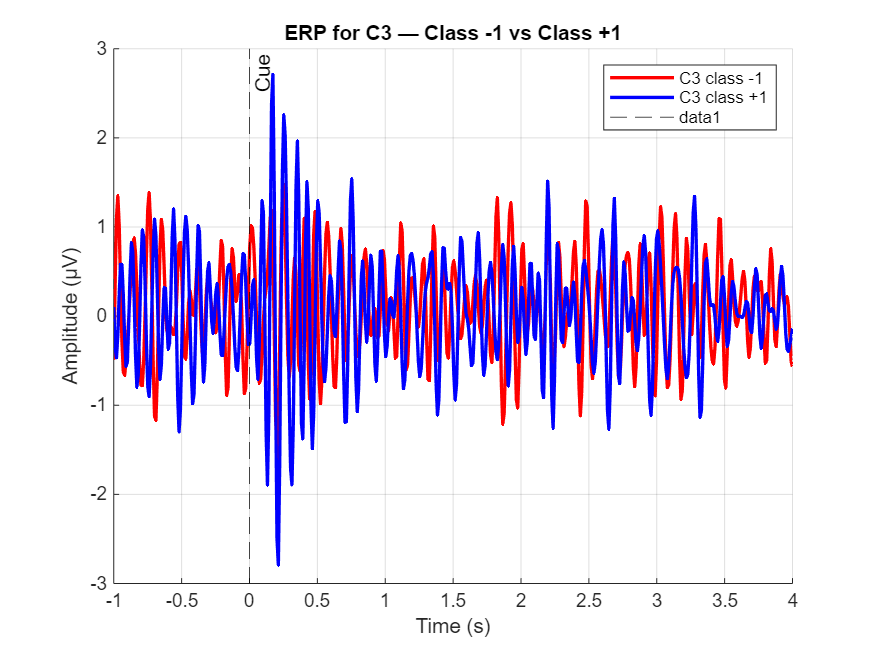



%% =======================
% 2. Select channels C3, C4, Cz
% =======================
channels = {'C3','C4','Cz'};

idx1 = find(ismember({EEG_class1.chanlocs.labels}, channels));
idx2 = find(ismember({EEG_class2.chanlocs.labels}, channels));


%% =======================
% 3. Compute ERPs (mean over trials)
% =======================
ERP_class1 = squeeze(mean(EEG_class1.data(idx1, :, :), 3));  % class -1
ERP_class2 = squeeze(mean(EEG_class2.data(idx2, :, :), 3));  % class +1


%% =======================
% 4. Build time vector
% =======================
fs = EEG_class1.srate;
samples = size(ERP_class1, 2);
time = linspace(epochWindow(1), epochWindow(2), samples);


%% =======================
% 5. Plot ERP for each class separately
% =======================
figure; hold on;

% Class -1 (e.g., left-hand imagery)
plot(time, ERP_class1(1,:), 'r', 'LineWidth', 1.6);   % C3 red
plot(time, ERP_class2(1,:), 'b', 'LineWidth', 1.6);   % C3 blue
xlabel('Time (s)');
ylabel('Amplitude (µV)');
title('ERP for C3 — Class -1 vs Class +1');
legend({ 'C3 class -1', 'C3 class +1'});
grid on;

% Mark cue onset
xline(0,'k--','Cue');

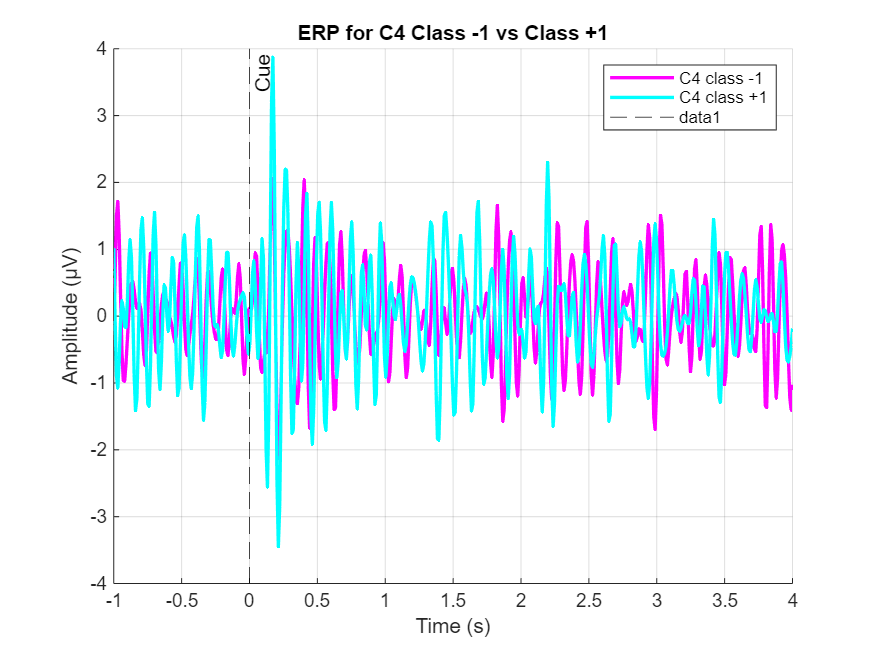

figure; hold on;
plot(time, ERP_class1(2,:), 'm', 'LineWidth', 1.6);   % C4 magenta
plot(time, ERP_class2(2,:), 'c', 'LineWidth', 1.6);
xlabel('Time (s)');
ylabel('Amplitude (µV)');
title('ERP for C4 Class -1 vs Class +1');
legend({ 'C4 class -1', 'C4 class +1'});
grid on;

% Mark cue onset
xline(0,'k--','Cue');% C4 cyan

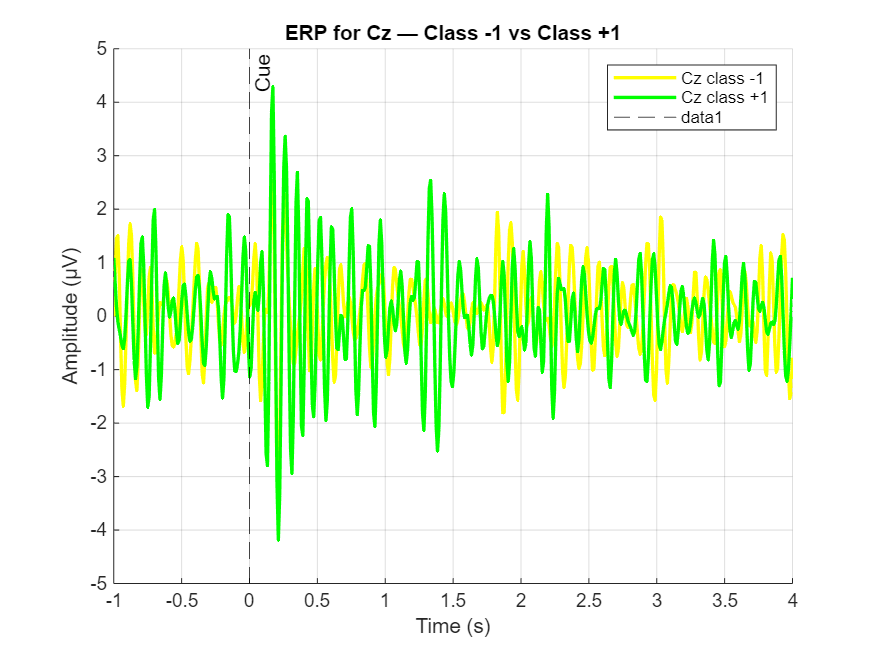



figure; hold on;
% Class +1 (e.g., right-hand imagery)
plot(time, ERP_class1(3,:), 'y', 'LineWidth', 1.6);   % Cz yellow
plot(time, ERP_class2(3,:), 'g', 'LineWidth', 1.6);   % Cz green

xlabel('Time (s)');
ylabel('Amplitude (µV)');
title('ERP for Cz — Class -1 vs Class +1');
legend({ 'Cz class -1', 'Cz class +1'});
grid on;

% Mark cue onset
xline(0,'k--','Cue');

hold off;

%% ==========================================
% PARAMETERS
% ==========================================
freqRange = [8 16];      % Hz
channels = {'C3','C4','Cz'};

%% ==========================================
% 1. Get channel indices
% ==========================================
idx_class1 = find(ismember({EEG_class1.chanlocs.labels}, channels));
idx_class2 = find(ismember({EEG_class2.chanlocs.labels}, channels));

%% ==========================================
% 2. Compute PSD for each channel separately
% ==========================================
PSD_class1 = computePSD_channels(EEG_class1, idx_class1, freqRange);

Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 1

PSD_class2 = computePSD_channels(EEG_class2, idx_class2, freqRange);

Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 100; fft length: 100; overlap 0):
.
Computing spectra (window length 1


%% ==========================================
% 3. Add labels (last column)
% ==========================================
for ch = 1:3
    PSD_class1{ch} = [PSD_class1{ch} zeros(size(PSD_class1{ch},1),1)];
    PSD_class2{ch} = [PSD_class2{ch} ones(size(PSD_class2{ch},1),1)];
end

%% ==========================================
% 4. Save datasets separately
% ==========================================
c3_PSD_trials_class1 = PSD_class1{1};
save('c3_PSD_trials_class1.mat','c3_PSD_trials_class1');
c4_PSD_trials_class1 = PSD_class1{2};
save('c4_PSD_trials_class1.mat','c4_PSD_trials_class1');
cz_PSD_trials_class1 = PSD_class1{3};
save('cz_PSD_trials_class1.mat','cz_PSD_trials_class1');

c3_PSD_trials_class2 = PSD_class2{1};
save('c3_PSD_trials_class2.mat','c3_PSD_trials_class2');
c4_PSD_trials_class2 = PSD_class2{2};
save('c4_PSD_trials_class2.mat','c4_PSD_trials_class2');
cz_PSD_trials_class2 = PSD_class2{3};
save('cz_PSD_trials_class2.mat','cz_PSD_trials_class2');

disp('Saved 6 PSD datasets (per channel per class)');

Saved 6 PSD datasets (per channel per class)



%% ==========================================
% Helper function
% ==========================================
function PSD_cell = computePSD_channels(EEG, chanIdx, freqRange)
    numCh = length(chanIdx);
    PSD_cell = cell(numCh,1);

    for ch = 1:numCh
        PSD_trials = zeros(EEG.trials, 9); % 9 frequency bins
        for tr = 1:EEG.trials
            data = EEG.data(chanIdx(ch), :, tr);
            [spectra, freqs] = spectopo(data, 0, EEG.srate, 'plot','off');
            % select 8–16 Hz
            mask = freqs>=freqRange(1) & freqs<=freqRange(2);
            PSD_vals = spectra(mask);
            PSD_trials(tr,:) = PSD_vals(:)'; % 1x9
        end
        PSD_cell{ch} = PSD_trials;
    end
end


%% ==========================================
% Load datasets
% ==========================================
clear;
clc;
load('c3_PSD_trials_class1.mat'); c3_class1 = c3_PSD_trials_class1;
load('c4_PSD_trials_class1.mat'); c4_class1 = c4_PSD_trials_class1;
load('cz_PSD_trials_class1.mat'); cz_class1 = cz_PSD_trials_class1;

load('c3_PSD_trials_class2.mat'); c3_class2 = c3_PSD_trials_class2;
load('c4_PSD_trials_class2.mat'); c4_class2 = c4_PSD_trials_class2;
load('cz_PSD_trials_class2.mat'); cz_class2 = cz_PSD_trials_class2;

channels = {'C3','C4','Cz'};
numFreqs = size(c3_class1,2)-1;  % 9 frequency bins
alpha = 0.05;

%% ==========================================
% 1. Frequency-wise unpaired t-tests per channel
%% ==========================================
fprintf('Frequency-wise t-tests per channel:\n');

Frequency-wise t-tests per channel:


tstats = struct();
for ch = 1:3
    fprintf('\nChannel: %s\n', channels{ch});
    PSD1 = eval([lower(channels{ch}) '_class1']); 
    PSD1 = PSD1(:,1:numFreqs);

    PSD2 = eval([lower(channels{ch}) '_class2']); 
    PSD2 = PSD2(:,1:numFreqs);
    
    pvals = zeros(1,numFreqs);
    for f = 1:numFreqs
        [~,p] = ttest2(PSD1(:,f), PSD2(:,f));
        pvals(f) = p;
        if p < alpha
            sig = '*';
        else
            sig = '';
        end
        fprintf('Freq bin %d: p = %.4f %s\n', f, p, sig);
    end
    tstats.(channels{ch}) = pvals;
end


Channel: C3


Freq bin 1: p = 0.3526 
Freq bin 2: p = 0.1697 
Freq bin 3: p = 0.5646 
Freq bin 4: p = 0.5217 
Freq bin 5: p = 0.4382 
Freq bin 6: p = 0.7294 
Freq bin 7: p = 0.5254 
Freq bin 8: p = 0.5901 
Freq bin 9: p = 0.2179 



Channel: C4


Freq bin 1: p = 0.5123 
Freq bin 2: p = 0.0278 *
Freq bin 3: p = 0.0738 
Freq bin 4: p = 0.5013 
Freq bin 5: p = 0.9621 
Freq bin 6: p = 0.3934 
Freq bin 7: p = 0.4598 
Freq bin 8: p = 0.3703 
Freq bin 9: p = 0.7627 



Channel: Cz


Freq bin 1: p = 0.1019 
Freq bin 2: p = 0.0099 *
Freq bin 3: p = 0.0004 *
Freq bin 4: p = 0.0002 *
Freq bin 5: p = 0.0816 
Freq bin 6: p = 0.5969 
Freq bin 7: p = 0.6404 
Freq bin 8: p = 0.1022 
Freq bin 9: p = 0.2067 


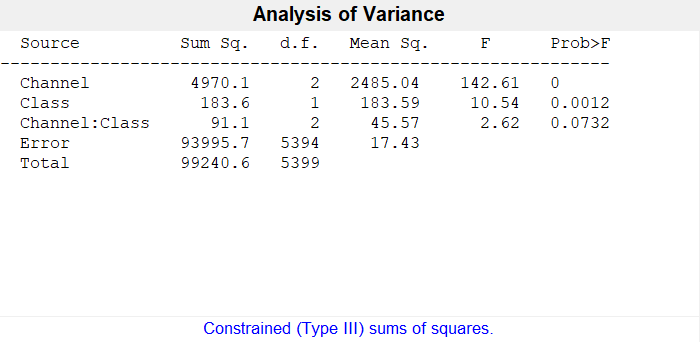



%% ==========================================
% 2. Two-way ANOVA: channel × class
% ==========================================
% Combine all data
all_PSD = [c3_class1(:,1:numFreqs); c4_class1(:,1:numFreqs); cz_class1(:,1:numFreqs); ...
           c3_class2(:,1:numFreqs); c4_class2(:,1:numFreqs); cz_class2(:,1:numFreqs)];
numTrials = size(c3_class1,1);
channel_labels = [ones(numTrials,1); 2*ones(numTrials,1); 3*ones(numTrials,1); ...
                  ones(numTrials,1); 2*ones(numTrials,1); 3*ones(numTrials,1)];
class_labels = [zeros(3*numTrials,1); ones(3*numTrials,1)]; % 0 = class1, 1 = class2

% Reshape PSD into long vector for ANOVA
Y = all_PSD(:);
Channel = repmat(channel_labels,numFreqs,1);
Class = repmat(class_labels,numFreqs,1);

[p,tbl,stats] = anovan(Y, {Channel,Class}, 'model','interaction','varnames',{'Channel','Class'});

- **F**: F-statistic for the effect

- **p**: significance value

**Interpretation:**

- If **p < 0.05** for **Channel**, PSD differs between C3, C4, Cz.

- If **p < 0.05** for **Class**, PSD differs between motor imagery classes.

- If **p < 0.05** for **Interaction**, the class effect depends on the channel (e.g., C3 may show strong difference but Cz may not).

disp('Two-way ANOVA (Channel × Class):');

Two-way ANOVA (Channel × Class):


disp(tbl);

    {'Source'       }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'Channel'      }    {[4.9701e+03]}    {[   2]}    {[        0]}    {[2.4850e+03]}    {[142.6055]}    {[4.4572e-61]}
    {'Class'        }    {[  183.5882]}    {[   1]}    {[        0]}    {[  183.5882]}    {[ 10.5353]}    {[    0.0012]}
    {'Channel:Class'}    {[   91.1470]}    {[   2]}    {[        0]}    {[   45.5735]}    {[  2.6153]}    {[    0.0732]}
    {'Error'        }    {[9.3996e+04]}    {[5394]}    {[        0]}    {[   17.4260]}    {0×0 double}    {0×0 double  }
    {'Total'        }    {[9.9241e+04]}    {[5399]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



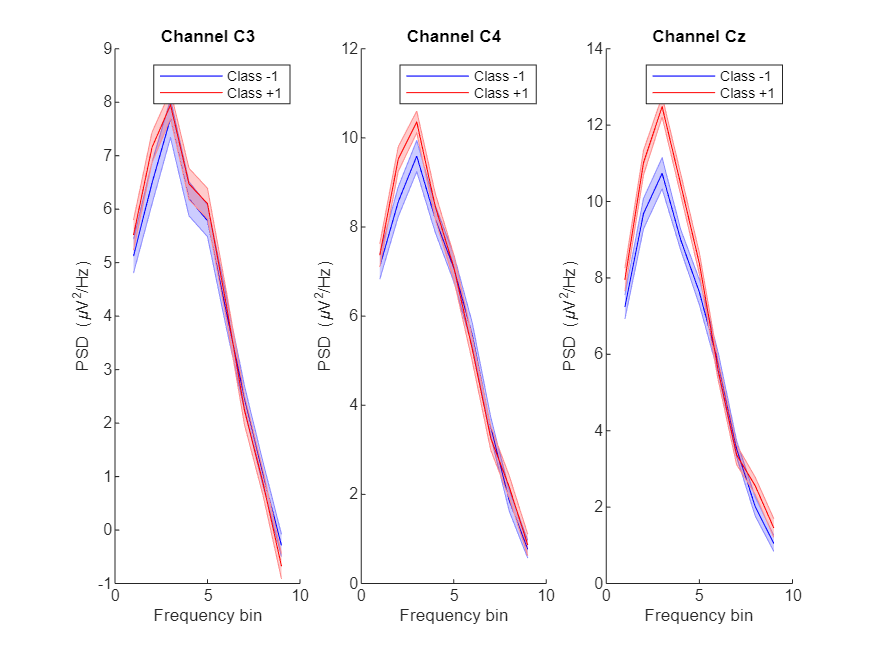


%% ==========================================
% 3. Plot mean ± SEM PSD per channel
% ==========================================
figure; 
hold on; 
colors = {'b','r'}; 
for ch = 1:3
    PSD1 = eval([lower(channels{ch}) '_class1']); 
    PSD1 = PSD1(:,1:numFreqs);
    PSD2 = eval([lower(channels{ch}) '_class2']); 
    PSD2 = PSD2(:,1:numFreqs);
    
    mean1 = mean(PSD1); 
    sem1 = std(PSD1)/sqrt(size(PSD1,1));
    mean2 = mean(PSD2); 
    sem2 = std(PSD2)/sqrt(size(PSD2,1));
    
    subplot(1,3,ch); hold on;
    freqBins = 1:numFreqs;
    shadedErrorBar(freqBins, mean1, sem1, 'lineprops','b'); % class1
    shadedErrorBar(freqBins, mean2, sem2, 'lineprops','r'); % class2
    xlabel('Frequency bin'); ylabel('PSD (\muV^2/Hz)');
    title(['Channel ' channels{ch}]);
    legend('Class -1','Class +1');
end

%% ==========================================
% Load datasets
% ==========================================
clear;
clc;
load('c3_PSD_trials_class1.mat'); 
c3_class1 = c3_PSD_trials_class1;
load('c4_PSD_trials_class1.mat'); c4_class1 = c4_PSD_trials_class1;
load('cz_PSD_trials_class1.mat'); cz_class1 = cz_PSD_trials_class1;

load('c3_PSD_trials_class2.mat'); c3_class2 = c3_PSD_trials_class2;
load('c4_PSD_trials_class2.mat'); c4_class2 = c4_PSD_trials_class2;
load('cz_PSD_trials_class2.mat'); cz_class2 = cz_PSD_trials_class2;

channels = {'C3','C4','Cz'};
numFreqs = size(c3_class1,2)-1;  % 9 frequency bins
alpha = 0.05;

%% ==========================================
% 1. Test normality using Lilliefors test
% ==========================================
fprintf('Lilliefors normality test per channel & frequency:\n');

Lilliefors normality test per channel & frequency:


normality_results = struct();

for ch = 1:3
    PSD1 = eval([lower(channels{ch}) '_class1']); 
    PSD1 = PSD1(:,1:numFreqs);
    PSD2 = eval([lower(channels{ch}) '_class2']); 
    PSD2 = PSD2(:,1:numFreqs);
    
    fprintf('\nChannel: %s\n', channels{ch});
    normFlags = zeros(numFreqs,2); % 1 = normal, 0 = non-normal
    
    for f = 1:numFreqs
        [h1,~] = lillietest(PSD1(:,f), 'Alpha', alpha);
        [h2,~] = lillietest(PSD2(:,f), 'Alpha', alpha);
        normFlags(f,1) = ~h1; % 1 = normal
        normFlags(f,2) = ~h2;
        fprintf('Freq bin %d: class -1 %s, class +1 %s\n', f, ...
            ternary_str(~h1,'normal','non-normal'), ...
            ternary_str(~h2,'normal','non-normal'));
    end
    normality_results.(channels{ch}) = normFlags;
end


Channel: C3


Freq bin 1: class -1 normal, class +1 normal
Freq bin 2: class -1 non-normal, class +1 normal
Freq bin 3: class -1 non-normal, class +1 normal
Freq bin 4: class -1 normal, class +1 normal
Freq bin 5: class -1 normal, class +1 normal
Freq bin 6: class -1 normal, class +1 normal
Freq bin 7: class -1 normal, class +1 normal
Freq bin 8: class -1 normal, class +1 normal
Freq bin 9: class -1 normal, class +1 normal



Channel: C4


Freq bin 1: class -1 normal, class +1 normal
Freq bin 2: class -1 normal, class +1 normal
Freq bin 3: class -1 normal, class +1 normal
Freq bin 4: class -1 normal, class +1 non-normal
Freq bin 5: class -1 normal, class +1 normal
Freq bin 6: class -1 normal, class +1 normal
Freq bin 7: class -1 normal, class +1 normal
Freq bin 8: class -1 normal, class +1 normal
Freq bin 9: class -1 normal, class +1 normal



Channel: Cz


Freq bin 1: class -1 normal, class +1 normal
Freq bin 2: class -1 non-normal, class +1 non-normal
Freq bin 3: class -1 non-normal, class +1 normal
Freq bin 4: class -1 normal, class +1 normal
Freq bin 5: class -1 normal, class +1 normal
Freq bin 6: class -1 normal, class +1 normal
Freq bin 7: class -1 normal, class +1 normal
Freq bin 8: class -1 normal, class +1 non-normal
Freq bin 9: class -1 normal, class +1 normal



%% ==========================================
% 2. Non-parametric test (Mann-Whitney U / ranksum)
% ==========================================
fprintf('\nMann-Whitney U test (ranksum) per channel & frequency:\n');


Mann-Whitney U test (ranksum) per channel & frequency:


pvals_ranksum = struct();

for ch = 1:3
    PSD1 = eval([lower(channels{ch}) '_class1']); PSD1 = PSD1(:,1:numFreqs);
    PSD2 = eval([lower(channels{ch}) '_class2']); PSD2 = PSD2(:,1:numFreqs);
    
    pvals = zeros(1,numFreqs);
    fprintf('\nChannel: %s\n', channels{ch});
    
    for f = 1:numFreqs
        p = ranksum(PSD1(:,f), PSD2(:,f));
        pvals(f) = p;
        sig = '';
        if p < alpha
            sig = '*';
        end
        fprintf('Freq bin %d: p = %.4f %s\n', f, p, sig);
    end
    pvals_ranksum.(channels{ch}) = pvals;
end


Channel: C3


Freq bin 1: p = 0.2862 
Freq bin 2: p = 0.3290 
Freq bin 3: p = 0.9348 
Freq bin 4: p = 0.4524 
Freq bin 5: p = 0.6734 
Freq bin 6: p = 0.9698 
Freq bin 7: p = 0.9795 
Freq bin 8: p = 0.7004 
Freq bin 9: p = 0.3653 



Channel: C4


Freq bin 1: p = 0.5535 
Freq bin 2: p = 0.0674 
Freq bin 3: p = 0.1883 
Freq bin 4: p = 0.4437 
Freq bin 5: p = 0.8594 
Freq bin 6: p = 0.4793 
Freq bin 7: p = 0.8136 
Freq bin 8: p = 0.1205 
Freq bin 9: p = 0.3640 



Channel: Cz


Freq bin 1: p = 0.1211 
Freq bin 2: p = 0.0290 *
Freq bin 3: p = 0.0047 *
Freq bin 4: p = 0.0001 *
Freq bin 5: p = 0.1377 
Freq bin 6: p = 0.6557 
Freq bin 7: p = 0.7443 
Freq bin 8: p = 0.0508 
Freq bin 9: p = 0.1907 




function out = ternary_str(cond, valTrue, valFalse)
    if cond
        out = valTrue;
    else
        out = valFalse;
    end
end



